%-- 21/04/2025 21:30 --%
%the constants for voltage to speed
a = 5 * 10^-5

a = 5.0000e-05

b= 0.000505

b = 5.0500e-04

c = 0.2005

c = 0.2005

% now create the T(s) = H/(1+H)
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


H = 1/(a*s^2+b*s+c)

H =
 
                 1
  -------------------------------
  5e-05 s^2 + 0.000505 s + 0.2005
 
Continuous-time transfer function.
Model Properties


T_H = H/(1+H)

T_H =
 
                   5e-05 s^2 + 0.000505 s + 0.2005
  -----------------------------------------------------------------
  2.5e-09 s^4 + 5.05e-08 s^3 + 7.031e-05 s^2 + 0.0007075 s + 0.2407
 
Continuous-time transfer function.
Model Properties


 % angular variables 
num = 0.06999

num = 0.0700

den = [0.03266 0.001 -0.6867]

den =     0.0327    0.0010   -0.6867


% The angular transfer
A = tf(num, den)

A =
 
             0.06999
  ------------------------------
  0.03266 s^2 + 0.001 s - 0.6867
 
Continuous-time transfer function.
Model Properties


T_A = A/(1+A)

T_A =
 
                0.002286 s^2 + 6.999e-05 s - 0.04806
  ----------------------------------------------------------------
  0.001067 s^4 + 6.532e-05 s^3 - 0.04257 s^2 - 0.001303 s + 0.4235
 
Continuous-time transfer function.
Model Properties


% להרכיב את שתי הפנוקציות זה על זו משמע להכפיל אותן
K = A*H

K =
 
                                0.06999
  -------------------------------------------------------------------
  1.633e-06 s^4 + 1.654e-05 s^3 + 0.006515 s^2 - 0.0001463 s - 0.1377
 
Continuous-time transfer function.
Model Properties


T_K = K/(1+K)

T_K =
 
                                1.143e-07 s^4 + 1.158e-06 s^3 + 0.0004559 s^2 - 1.024e-05 s - 0.009636
  -----------------------------------------------------------------------------------------------------------------------------------
  2.667e-12 s^8 + 5.403e-11 s^7 + 2.155e-08 s^6 + 2.151e-07 s^5 + 4.21e-05 s^4 - 5.304e-06 s^3 - 0.001338 s^2 + 3.004e-05 s + 0.00932
 
Continuous-time transfer function.


%create functions for evaluating OS and ESS

%OS implomentation
function topTwo = top2real(cnums)
%TOP2REAL Returns the 2 complex numbers with the largest real parts
%   Input:  cnums - array of complex numbers
%   Output: topTwo - 1x2 array of complex numbers with largest real parts

    if length(cnums) < 2
        error('Input must contain at least two complex numbers.');
    end

    % Get the real parts
    realParts = real(cnums);

    % Sort indices of real parts in descending order
    [~, sortedIndices] = sort(realParts, 'descend');

    % Select top 2
    topTwo = cnums(sortedIndices(1:2));
end

function uncanceledPoles = getUncanceledPoles(sys)
%GETUNCANCELEDPLOES returns poles that are not canceled by zeros
% Input:  sys - transfer function (tf)
% Output: uncanceledPoles - list of poles that are not canceled

    % Get poles and zeros
    p = pole(sys);
    z = zero(sys);

    % Initialize list of uncanceled poles
    uncanceledPoles = p;

    % Remove poles that are canceled by zeros (within tolerance)
    tol = 1e-6;
    for i = 1:length(z)
        % Find the index of the first pole that matches the zero
        idx = find(abs(uncanceledPoles - z(i)) < tol, 1);
        if ~isempty(idx)
            % Remove this pole from the list
            uncanceledPoles(idx) = [];
        end
    end
end


function OS = overshoot(sys)
%Calculates the overshoot
%takes in an entire transfer of a system
uncanceled = getUncanceledPoles(sys);
% takes only the 2 dominate poles
releventPoles = top2real(uncanceled);
%now calculate
omega = sqrt(releventPoles(1)*releventPoles(2));
b = releventPoles(1) + releventPoles(2);
xi = b/(2*omega);
OS = exp(-pi * xi / sqrt(1-xi^2));

end

function ess = Ess_calc(tf)
%takes in a transfer of a function
E_s = 1/(1+tf);
%limit at 0
ess = evalfr(E_s, 1e-6);
end


The following rlocuses will give us how the transfers realy look like

rlocus(H)
overshoot(H)

ans = 1.2857

Ess_calc(H)

ans = 0.1670

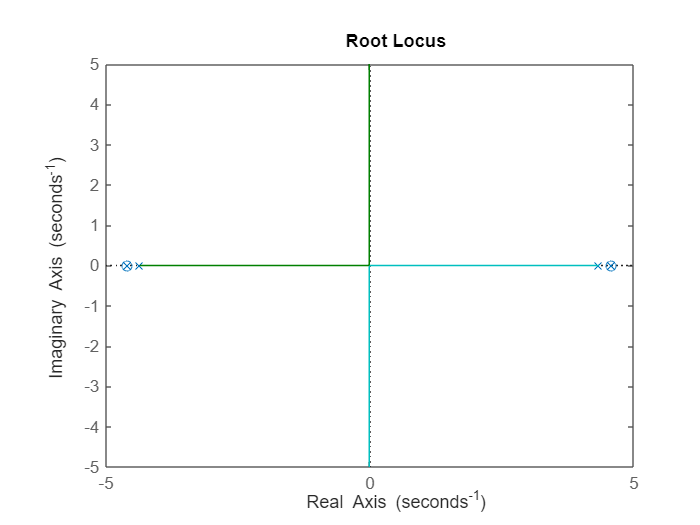

rlocus(T_A)

overshoot(T_A)
Ess_calc(A)

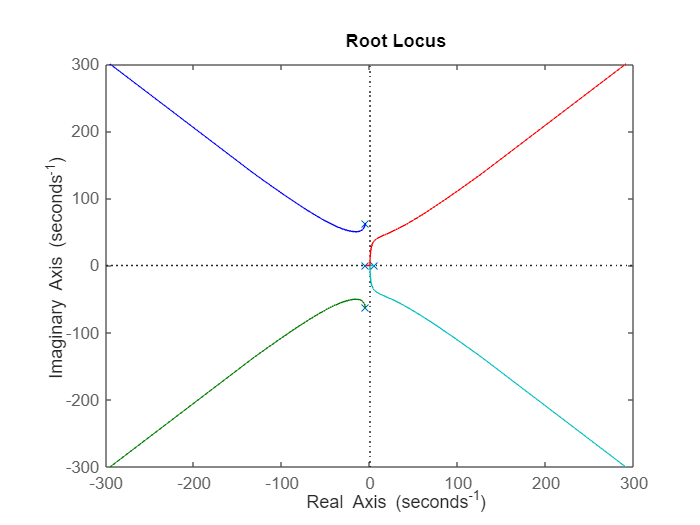

rlocus(K)

overshoot(K)

ans = 0.9999 - 0.0105i

Ess_calc(K)

ans = 1.0005

Now we play with the function K. What i tried to do here is to create a control function that when put on K it gives a controlled K that is stable

numCon = [1 2 100]

numCon =      1     2   100


denCon = 1

denCon = 1

controller = tf(numCon,denCon)

controller =
 
  s^2 + 2 s + 100
 
Continuous-time transfer function.
Model Properties



CtrlK = K*controller

CtrlK =
 
                     0.06999 s^2 + 0.14 s + 6.999
  -------------------------------------------------------------------
  1.633e-06 s^4 + 1.654e-05 s^3 + 0.006515 s^2 - 0.0001463 s - 0.1377
 
Continuous-time transfer function.
Model Properties


T_Ctrl_K = CtrlK/(1+CtrlK)

T_Ctrl_K =
 
                  1.143e-07 s^6 + 1.386e-06 s^5 + 0.0004697 s^4 + 0.001017 s^3 + 0.03594 s^2 - 0.0203 s - 0.9636
  -------------------------------------------------------------------------------------------------------------------------------
  2.667e-12 s^8 + 5.403e-11 s^7 + 1.358e-07 s^6 + 1.602e-06 s^5 + 0.0005117 s^4 + 0.001011 s^3 + 0.03414 s^2 - 0.02026 s - 0.9447
 
Continuous-time transfer function.


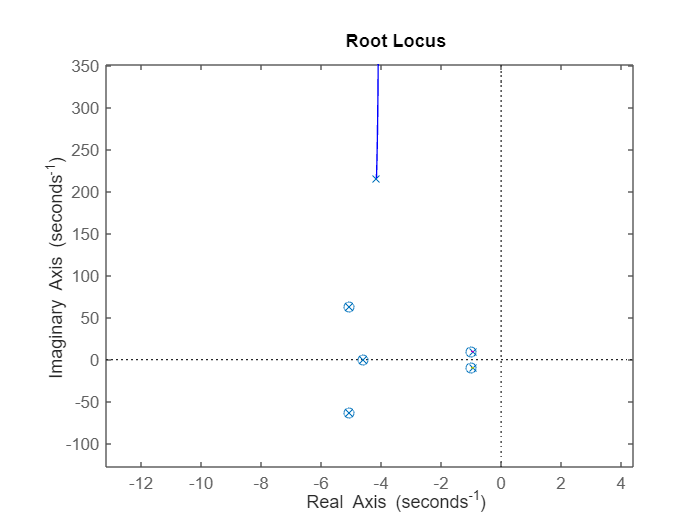

rlocus(T_Ctrl_K)